# Noctilucent Clouds: How to Verify a Sighting

### Introduction

Among the most beautiful of all cloud displays are noctilucent clouds, the highest and coldest of all clouds produced on Earth. NLCs form at the top of the mesosphere (~50 miles) at temperatures around -250F.  They are only visible in the hours after sunset at mid to upper latitudes (~45º-60º latitude) in a 3-4 weeks surrounding the summer solstice. Long after the sun has set to surface observers, noctilucent clouds are still illuminated by the sun due to their altitude. This demo explores an NLC event I witnessed from Moscow, Idaho, (~47º N) on July 2 and 4, 2011. We will focus on the July 2 case.

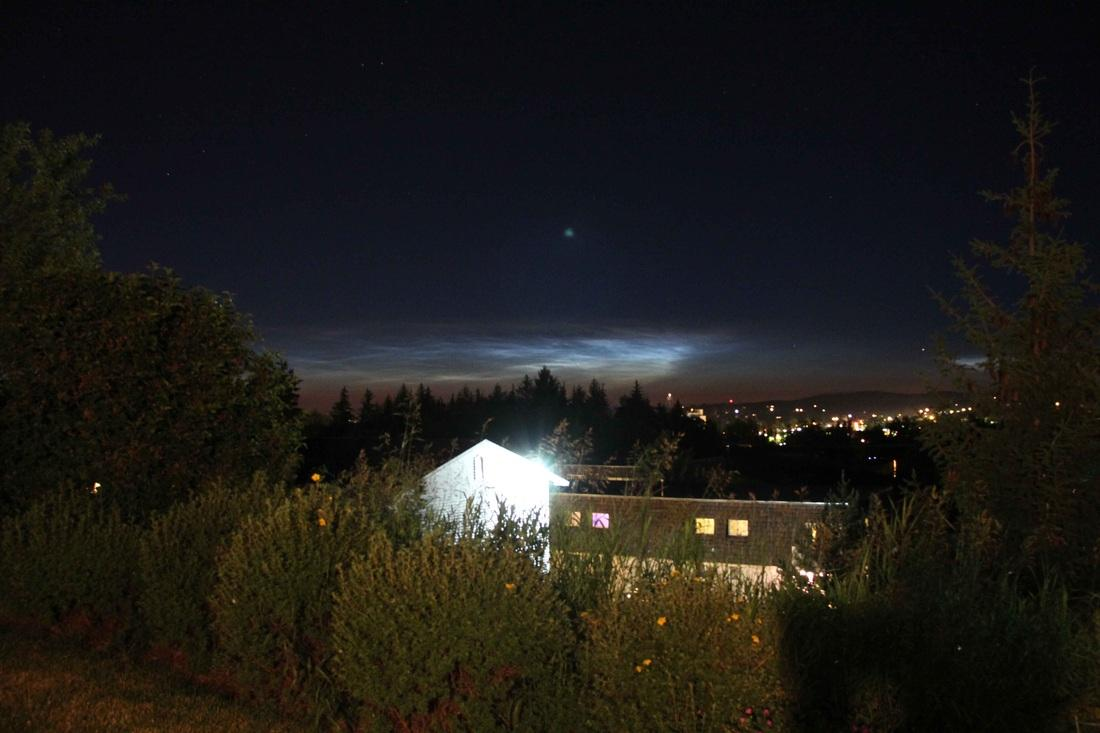

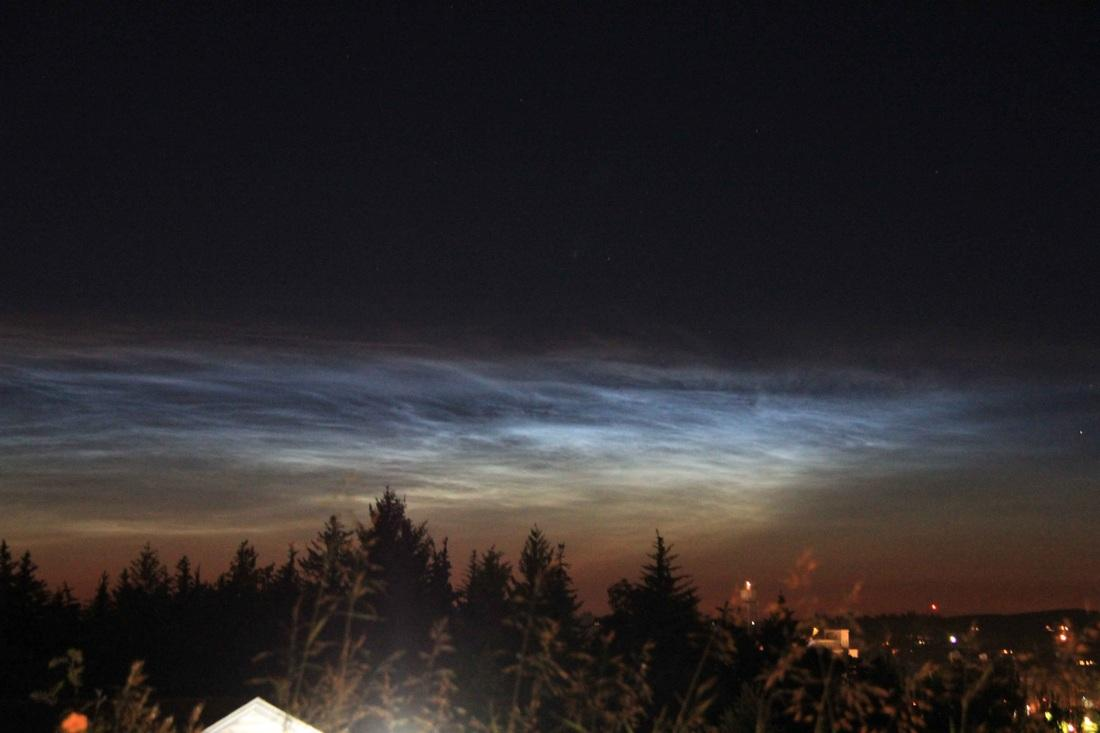

The maximum elevation angle of the illuminated portion of a noctilucent cloud is bounded by the Earth's shadow (the boundary of sunlight and twilight), unless the physical boundary of the cloud lies between the horizon and twilight's edge. Though it is not possible to directly calculate a noctilucent cloud's altitude from a single position using geometry alone, it is possible to converge on the altitude of the observed feature by calculating the elevation angle for a particular altitude that corresponds to the edge of the sunlit portion of the sky from the observer's perspective. Following Warren etal. (1997) and Gadsden & Schröder (1989) we will plot the elevation angles from 50-90 km altitude. 

### Some details about the July 2011 event

Widespread NLC reports from western North America were made over three consequtive nights from July 1-4, 2011, particularly the first night, which when our case was occurred. According to Mark Zalcik, who compiled sighting for [NLC CAN AM](https://www.ed-co.net/nlc/) (now [NLCNET](https://ed-co.net/nlcnet/), I believe), reports came from dozens of observers in Seattle, Alberta, Idaho, and North Dakota. They were even observed unusually far south, at 39º from aircraft. This is a copy of the reports I sent to Mr. Zalcik. The report can be decoded [here](https://www.ed-co.net/nlc/nlcobser.htm). You can see that the window of time they are visible is very brief, just 10-15 minutes.

% 07/02/2011 (UTC)
% Sunset: 03:45 UTC 
% First noticed: 05:30 UTC 
% 
% **********************************************************************************
% NOCTILUCENT CLOUD REPORT
% 
% 
% OBSERVER:  Christopher J Cox
% LOCATION:  Moscow, Idaho:  46d43'54"N 116d59'50"W
% DATE:      2011 07-02 (UTC)
% 
% Time      Elevation
% UT        h        /  Azimuth   Forms      Bright  Notes
% 05:35		<10         280-340   II & III   3-4     Bright display mostly centered ~315d +/- 10d  
% 05:45		<10         280-340   II & III   1-2     Display changed little but became dimmer
% 06:00                                      1       Very faint
% 
% No further observations.
% **********************************************************************************

% 07/03/2011 (UTC)
% Sunset: 
% First noticed: 05:00 UTC
% 
% **********************************************************************************
% NOCTILUCENT CLOUD REPORT
% 
% 
% OBSERVER:  Christopher J Cox
% LOCATION:  Moscow, Idaho:  46d43'54"N 116d59'50"W
% DATE:      2011 07-04 (UTC)
% 
% Time      Elevation
% UT        h        /  Azimuth   Forms      Bright  Notes
% 05:00     10-15       315-330              1-2     Most of lower elev angle of display obscured by lower clouds 
% 05:15	    10-15       315-330              1       Most of lower elev angle of display obscured by lower clouds
% 05:20                                      0       Gone 
% 
% 
% No further observations.
% **********************************************************************************

### Step 1. Parameters of the observation 

For the analysis, the key observations are the time and location, from which the solar geometeries can be calculated, and the azimuthal and zenith ranges over which the cloud features are spotted. 

clc; clear all; close all;
location.longitude = -116.9972                     ; % [deg +E]
location.latitude  = 46.7317                       ; % [deg +N]
location.altitude  = 787                           ; % [m]
time               = datenum([2011 7 2 5 35 0])    ; % date YYYY MM DD hh mm ss
CldAz              = 280:340                       ; % [deg] cloud azimuth angle (observed)

% I use a function based on Reda & Andreas (2003) coded by Rino (2025).
if exist('sun_position') == 2
    sun = sun_position(time, location)             ;
    SunAz = sun.azimuth                            ; % [deg] solar azimuth angle
    B0    = sun.zenith - 90                        ; % beta is solar depression angle, no account for refraction
else
    SunAz = input('Enter solar azimuth angle.')    ; % [deg] solar azimuth angle
    B0    = input('Enter solar depression angle.') ; % beta is solar depression angle, no account for refraction
end

### Step 2. Prerequisites

% Set up
as    = CldAz-SunAz                                ; % azmuth from sun
hts   = (50:10:90)*1000                            ; % cloud height
t0    = 0                                          ; % theta, the angle outside meridian plane
R     = 6371*1000                                  ; % km, constant, radius of earth
H     = 15000                                      ; % nominal scale height [m], Gadsden (1989) pg. 25 & Warren (1997)
rSun  = 0.27                                       ; % radius of sun
rAtm  = 0.16                                       ; % refraction from atmosphere: 1000mb, 15C, 5d elv. http://wise-obs.tau.ac.il/~eran/Wise/Util/Refraction.html
rB    = 0.10                                       ; % refraction of incident to screening ht. just a guess using Warren 1997.
B0    = B0 - rSun - rAtm - rB ;

% convert beta, theta, and a to radians
a     = as .* (pi/180)                             ;
B     = B0 .* (pi/180)                             ;
t     = t0 .* (pi/180)                             ;

### Step 3. Calculate

E = NaN(length(hts),length(as));
for ind = 1:length(hts)
    h = hts(ind);
    
    for ind2 = 1:length(a)
        a0 = a(ind2);
    
        % Gadsden (1989) eq. 3.2
        Y = sqrt( (R+h)^2 - (R+H)^2 );

        % Gadsden (1989) eq. 3.4 to include azimuth
        S = sqrt( ( (Y-R*sin(B))^2 + (R*cos(B) - (R+H)*cos(t))^2 ) / (1/2 + 1/2*cos(2*a0)) ); 

        % Gadsden (1989) eq. 3.3
        E(ind,ind2) = (asin( ( Y*sin(B) - R+(R+H)*cos(t)*cos(B) ) / S ));
    end

end
E = E .* (180/pi);

### Step 4. Make a figure

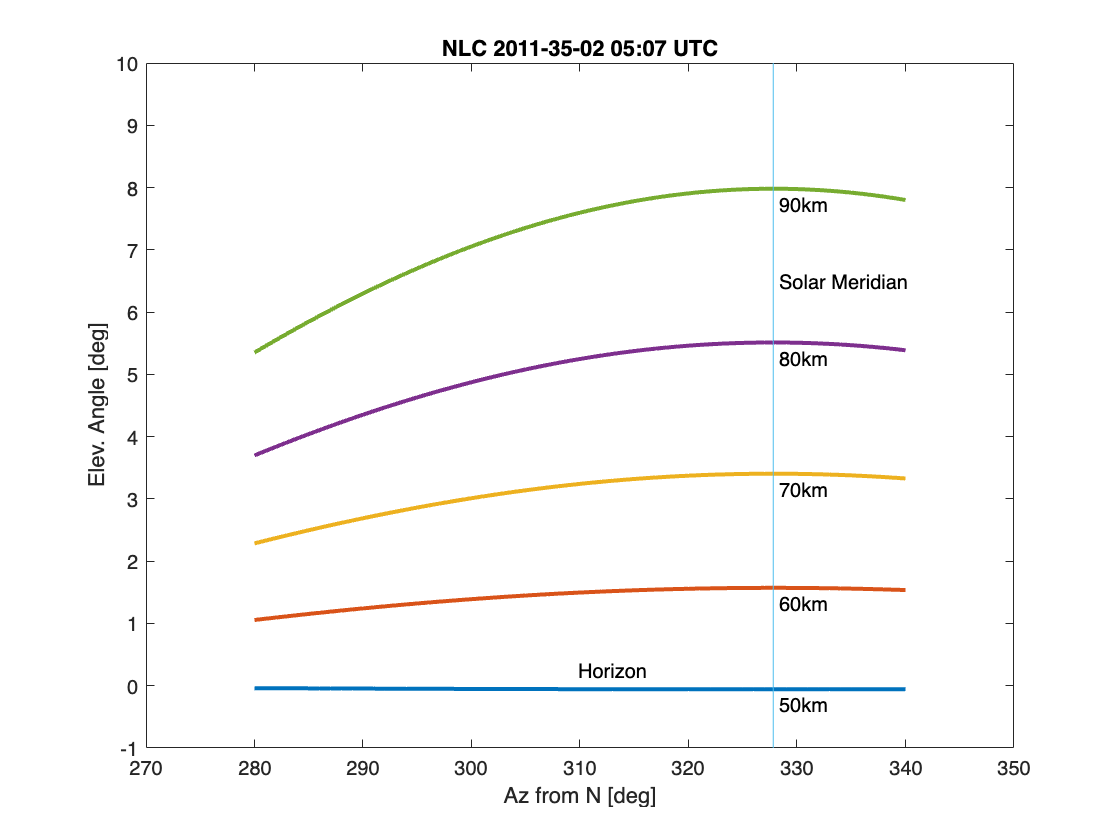

for k = 1:length(hts)
    plot(as+SunAz,E(k,:),'linewidth',2); hold on
    text(SunAz+0.5,max(E(k,:))-0.25,[num2str(hts(k)/1000),'km']);
end
ylim([-1 10])
xlim([min(as+SunAz)-10 max(as+SunAz)+10])
xlabel('Az from N [deg]');
ylabel('Elev. Angle [deg]');
title(['NLC ',datestr(time,'YYYY-MM-DD hh:mm UTC')])
line([SunAz SunAz],[-1 10])
text(SunAz+0.5,6.5,'Solar Meridian');
text(SunAz-18,0.25,'Horizon');

### Step 5. Interpretation

Though I was unable to measure the elevation angle directly, I estimated that it was < 10 degrees using the hand method. The figure shows that if the upper extent of the sunlit portion of the cloud was at the horizon from my perspective, the cloud would be 50 km high (50 km is within the stratopause, a portion of the atmosphere where clouds do not form). However, since the cloud edge appeared to be 5-10 degrees off the horizon, the cloud was at least 80 km high, consistent with the part of the atmosphere where NLCs would be expected to be found.

1) I assume the cloud sunlit boundary was an apparent edge and not a physical edge. Any account for the physical boundary existing first would effectively increase the reach of the cloud shadow in the calculation, making the calculation of cloud altitude higher.

2) I have not accounted for the surface elevation of Moscow, Idaho, where these observations occurred (~2600'). To account for this in the plot simply subtract 0.8 km from each of the altitude labels (e.g. 80 km becomes 79.2 km). A modest error compared to:

3) ...a few guesses for paremeters under "set up".

4) The azimuthal extent of the blue lines represent the azimuthal extent of the observation.

### References

Gadsden, M. & W. Schröder (1989) *Nocilucent Clouds*, Springer-Verlag, New York.

Reda, I. & I. Andreas (2003) Solar position algorithm for solar radiation application. National Renewable Energy Laboratory (NREL). Technical report NREL/TP-560-34302. 

Rino, C. (2025). Full Vectorization of Solar Azimuth and Elevation Estimation [https://www.mathworks.com/matlabcentral/fileexchange/48594-full-vectorization-of-solar-azimuth-and-elevation-estimation](https://www.mathworks.com/matlabcentral/fileexchange/48594-full-vectorization-of-solar-azimuth-and-elevation-estimation), MATLAB Central File Exchange. Retrieved April 19, 2025.

Warren, S.G., G.E. Thomas, G. Hernandez, & R.W. Smith (1997) Noctilucent cloud observed in late April at South Pole Station: Temperature anomaly or meteoritic debris? Journal of *Geophysical Research - Atmospheres*, 102(D2), 1991-2000. [https://doi.org/10.1029/96JD02513](https://doi.org/10.1029/96JD02513) 